# Week 5 Homework

* Robert Garrone*

*Worcester Polytechnic Institute, regarrone@wpi.edu*

## Introduction:

The three problem statements are given as:

**Problem 5-1**

Describe all steps to  derive (3.56) and (3.57) for links 2 and 3 of the elbow manipulator shown in Figure 3.13.

***Note****: In the 2nd edition of Spong et al. the figure is Figure 5.8 and the equations are (5.25) and (5.26).*

**Problem 5-2**

Program the solution of Example 3.10 SCARA manipulator in Matlab. use the path defined by (in meters):

x = 0.3 + 0.1*sin(0.5*pi*t); 

y = 0.1 + 0.1*cos(0.5*pi*t); 

z = 0.05 + 0.01*sin(0.1*pi*t); 

Draw profile of all the joint angles.

**Problem 5-3**

Repeat problem 5-2, but now using the Robotics System Toolbox (you can use the example from Week 4 as a starting point).

Use the function "robotics.InverseKinematics" or "generalizedInverseKinematics" (The last one is only available in Matlab2019).  (https://www.mathworks.com/help/robotics/ref/inversekinematics-system-object.html)

EDIT:  You can consider the orientation of the end-effector static, i.e. use an identity matrix in the rotation part of your homogeneous transformation.

Please, briefly discuss the limitations and advantages of using the inversekinematics function, not only for this assignment, but in general.

Hints:

- EDIT: Check the Discussion forum

- Use the configuration from one step behind as the "intial guess"

- Check the joint limits! (see PositionLimits)

### Approach:

#### Problem Statement V-1:

The approach consists of using trigonometric relationships to relate the given arm lengths and end effector position to the joint angle variables $\theta_2 \;\textrm{and}\;\theta_3$ considering that the side projection of the manipulator is also given. The relationships for $\theta_2 \;\textrm{and}\;\theta_3$ are expressed in terms of `atan2` in Spong, so it is necessary to convert any expression for the joint variables into one that uses `atan2`. `atan2` allows for the retention of quadrant information with regards to the angle and is thus more useful than a single-input `atan` function where signed inputs yield angle values agnostic to the quadrants that the input x and y values represent. 

#### Problem Statement V-2:

The approach consists of using the geometric approach to the inverse kinematics problem to manually derive expressions for the individual joint variables in terms of the trigonometric relationships between the link lengths. This is accomplished by projecting the manipulator onto 2-d planes to analyze the manipulator and compute the expressions for the joint variables. Once the expressions are obtained, the expressions are programmed into MATLAB and exercised for the end-effector coordinate path defined by the given sinusoidal equations for each of the x, y and z coordinates. The joint positions are then graphed and the effect of varying the link lengths on the joint paths is studied with the help of slide controls. 

#### Problem Statement V-3:

The approach consists of evaluating the available inverse kinematics solver algorithms and weighing their merits. Once a suitable algorithm is chosen, the SCARA manipulator is modelled using the MATLAB Robotics Toolbox and the `examplescara.m` demo file given in Week 4. The `inverseKinematics` solver is then used to obtain the individual joint positions for the SCARA manipulator for the same end effector path as in Problem Statement V-2. These computed joint positions are then plotted for each joint variable so that they may be compared to the graphs gotten in Problem Statement V-2.

## Materials and Methods:

### General Methodology:

Inverse kinematics is the process of determining the mathematical relationships of the individual joint variables needed to place the end effector in a given position. This is the opposite of forward kinematics where given the individual joint variables the position of the end effector is calculated. Inverse kinematics is generally a more challenging operation that forward kinematics. Whereas the forward kinematics problem always has a unique solution that can be obtained by evaluating the forward equations, the inverse kinematics problem may or may not have a solution and a solution, if it exists, may not be unique.

Given the difficulty of finding the general solution to the inverse kinematics problem, manipulator designs are typically restricted to the five most common configurations. With this in mind, it is appropriate to use a geometric approach for finding the end effector to joint variable relationships.

The premise behind the geometric approach is to solve for the individual joint variables by projecting the 3 dimensional manipulator onto a 2-dimensional plane and relate the joint variable to known manipulator geometric elements using trigonometry. It is desirable, when considering revolute joints, to express the variable in terms of a two argument arctangent or atan2. This way, the quadrant information is retained for the angle computed.

The alternative approach is to use a numerical algorithm to solve for the individual joint variables. This is an increasingly feasible approach given the available computing power and software. In some cases, a numerical algorithm is the best option for solving difficult inverse kinematics problems. 

### Problem Statement V-1:

Given a projection of a manipulator onto a 2-axis plane, the trigonometric tools most helpful for determining the equation relating the joint angle variables to the physical attributes of the manipulator are:

- The general trigonometric relationships and identities (i.e. definitions of sine cosine and tangent and their various identities)

- The Law of Cosines

- The Pythagorean theorem

Such is the case with the elbow manipulator presented in Figure 5.4 of Spong et al.

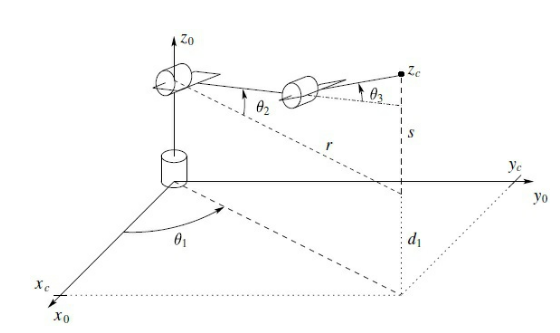

It is easy to see that, provided $x_c \not= y_c \not= 0$ that,


$$\theta_1 =\textrm{atan2}\left(x_c ,y_c \right)$$


Here, the projection of the manipulator onto the $x_c -y_c$ plane is implicitly considered. 

This manipulator configuration loses a degree of freedom in a *singlular* configuration of the arm. Specifically if $x_c =y_c =0$ the manipulator takes on the pose below.

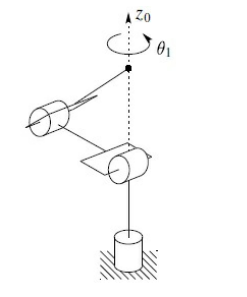

That is to say that in this particular position, the rotation about the $z_0$ axis by $\theta_1$ no longer has influence on the position of the end effector or wrist center at the end of the kinematic chain. This loss of a degree of freedom can be mitigated by including a shoulder offset at one of the links (shown below for either case) so that the wrist center (or end effector frame origin) may not intersect the base frame's $z_0$ axis.

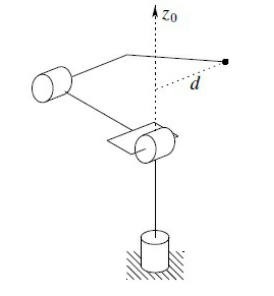 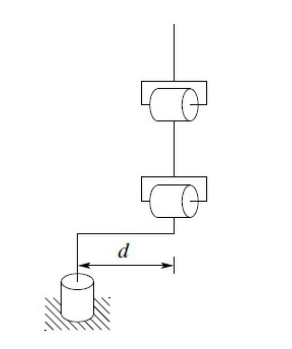

For the case of an articulated manipulator with a shoulder offset, the projection of the manipulator onto the $x_0 -y_0 \;$(and also the $x_c -y_c$ plane) looks like:

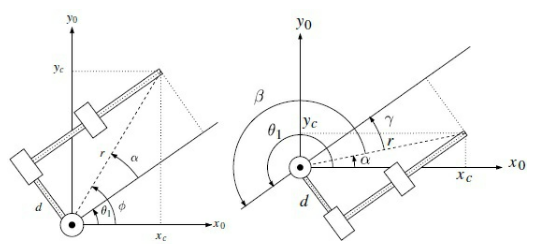

For the "left shoulder" and "right shoulder" configurations, respectively. To get $\theta_1$ in terms of an , Spong et al. performs a series of trigonometric operations to deduce solutions for both cases.

For the first case we see that


$$\theta_1 =\phi -\alpha$$


$\alpha$ is obtained by an `atan2` relationship - the adjacent side is $\textrm{rcos}\left(\alpha \right)$ and the opposite side is $\textrm{rsin}\left(\alpha \right)$. Put another way the adjacent side is $\sqrt{r^2 -d^2 }$ and the opposite side is, *d. *This yields,


$$\alpha =\textrm{atan2}\left(\sqrt{r^2 -d^2 },d\right)$$


Similarly, we also see an arctangent relationship for $\phi$:


$$\phi =\textrm{atan2}\left(x_c ,y_c \right)$$


Therefore, subtracting $\alpha$ from $\phi$ yields,


$$\theta_1 =\phi -\alpha =\textrm{atan2}\left(x_c ,y_c \right)-\textrm{atan2}\left(\sqrt{r^2 -d^2 },d\right)$$


In the second (left arm) case $\theta_1$ is


$$\theta_1 =\phi -\alpha =\textrm{atan2}\left(x_c ,y_c \right)+\textrm{atan2}\left(-\sqrt{r^2 -d^2 },-d\right)$$


The left arm case is essentially just the right arm case with a 180 degree rotation about $z_0$ and a 180 degree rotation about $z_1$ of the second joint. Spong gives several relationships for the variables at play:

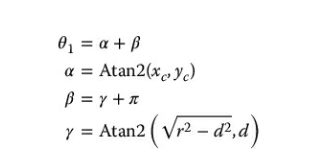

Because $\beta =\gamma +\pi$ and $\gamma =\textrm{Atan2}\left(\sqrt{r^2 -d^2 },d\right)$, the addition of $\pi$is equivalent to negating both atan2 terms (i.e. going from quadrant 1 to quadrant 3). $\beta$ is therefore


$$\beta =\textrm{atan2}\left(-\sqrt{r^2 -d^2 },-d\right)$$


and $\theta_1$ is,


$$\theta_1 =\alpha +\beta =\textrm{atan2}\left(x_c ,y_c \right)+\textrm{atan2}\left(-\sqrt{{x_c }^2 +y_c^2 -d^2 },-d\right)$$


(note that hypotenuse $r=x_c^2 +y_c^2$).

This same treatment can be applied to the articulated manipulator to solve $\theta_2 \;\textrm{and}\;\theta_3$ by viewing the manipulator from the side projection shown below.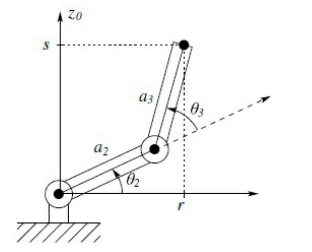

### Problem Statement V-2:

As in Problem statement V-1, the inverse kinematic equations of a SCARA manipulator can be solved using trigonometry. Spong et al. provides an example of a SCARA manipulator whose variables are solved by the geometric approach to deriving the inverse kinematic equations. We are given the figure of a SCARA manipulator below.

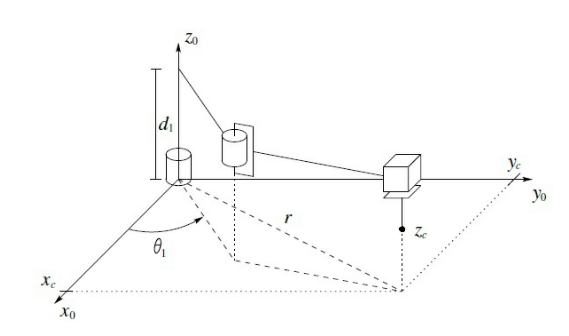

The total transfrom $T_4^1$ for this manipulator (less the transform from frame 0 to frame 1) is given as:

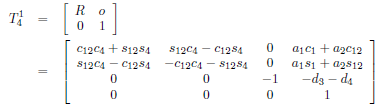

From this, Spong states that due to the limitations of this 4DOF manipulator, the rotational element of this transformation must be in the form:

$\alpha$ is given as a sum relationship of the 3 variable joint angles 


$$\alpha =\theta_1 +\theta_2 -\theta_4$$


with $\theta_4 \;$being the rotation of the end effector tip of the SCARA manipulator. $\alpha$ can be put in terms of the arctangent relationship of the $r_{11} \;\textrm{and}\;r_{12}$ elements of the rotation matrix above :


$$\theta_1 +\theta_2 -\theta_4 =\alpha =\textrm{atan2}\left(r_{11} ,r_{12} \right)$$


The SCARA figure is reproduced below, with a "side" view projection onto the x-z plane and a  "top down" view projection onto the x-y plane. 

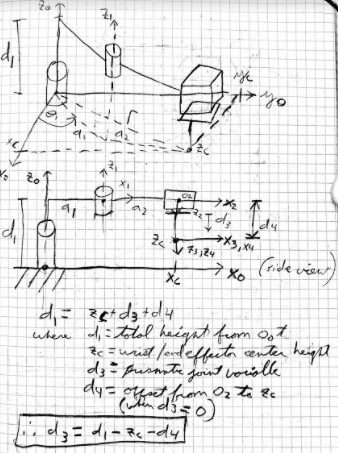

The side view projection onto the x-z plane can be used to derive the equation for the variable $d_3$. From the side view, it is apparent that 


$$d_1 =z_c +d_3 +d_4$$


where $d_1$is the z-axis total height of the manipulator from frame center 0 to frame centers 1 and 2, $z_c$ is the z coordinate of the end effector, $d_3$ is the prismatic joint variable and $d_4$ is the fixed offset between frames 2 and frames 3 and 4. Rearranging the above formula solves for variable $d_3$:


$$d_3 =d_1 -z_c -d_4$$
 

Revolute joints $\theta_1 \;\textrm{and}\;\theta_2$ are solved for in a method nearly identical to that of Problem Statement V-1. The "top-down" view of the SCARA manipulator is given below

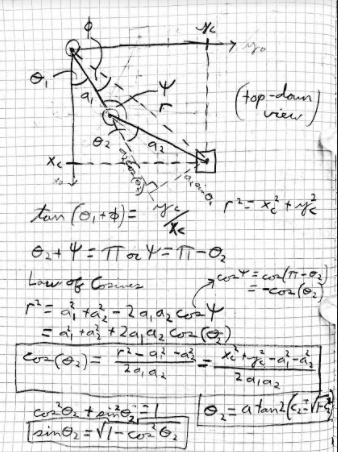

Hypotenuse *r* is drawn from the base frame origin to the end effector origin. Arms $a_1 \;\textrm{and}\;a_2$ are drawn with an angle $\psi$ between them. $\theta_1$ is the angle of arm $a_1$ relative to $x_0$ and $\theta_2$ is the angle of $a_2$ relative to $a_1$.$\phi$is the angle between *r* and $a_1$.

The Law of Cosines can be used to obtain the angle $\psi$ and by extension $\theta_2$ as shown in the calculations. $\theta_2$ can be gotten in an arctangent relationship as $\cos \left(\theta_2 \right)\;\textrm{and}\;\sin \left(\theta_2 \right)$ can be calculated.

As shown, $\tan \left(\phi +\;\theta_1 \right)=\frac{y_c }{x_c }$. $\phi$ can be solved for using an arctangent relationship as we know its opposite side is $a_2 \sin \left(\theta_2 \right)$ and its adjacent side is $a_1 +a_2 \cos \left(\theta_2 \right)$.

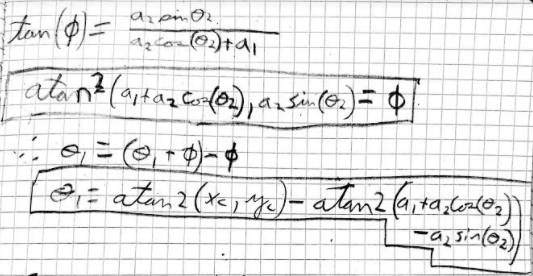

Finally, knowing $\phi$ in terms of an arctangent allows for the subtraction of $\phi$ from $\phi +\theta_1$ to yield $\theta_1$ as shown above. 

With $\theta_1 \;\textrm{and}\;\theta_2$ now known, it is possible to solve for $\theta_4$ in terms of arctangents. 

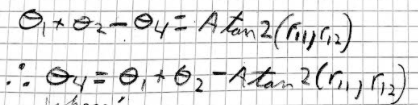

If we take the end effector orientation to be static, then the rotation matrix is


$$R=\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$


 $r_{11} =1$ and $r_{12} =0$. In this case atan2 evaluates to 0 and the resulting equation for $\theta_4$ is


$$\theta_4 =\theta_1 +\theta_2$$


### Problem Statement V-3:

An alternative to the geometric approach taken for Problem Statement V-1 and V-2 is to solve the inverse kinematic problem by using a numerical algorithm. Numerical methods are increasingly popular due to the availability of high-performancing computing and open-source software. In fact, in cases where the closed-form solution does not exist or if the manipulator is redundant, then numerical methods are often the better option.

In general, if $x^d$ is a vector in $\Re^m$ where $x^d$ might reoresebt the wrist center if m=3 or the end effector position and orientation for m=6. The forward kinematics of an *n-*link manipulator is a function that maps $\Re^n \to \Re^m$.  

If we set 


$$G\left(q\right)=x^d -f\left(q\right)$$


then a solution to the inverse kinematics problem is a configuration $q^d$ satisfying $G\left(q^d \right)=x^d -f\left(q^d \right)=0$. There are several numerical algorithms that are able to satisfy this equation. Spong discusses the Jacobian Inverse method and the Jacobian Transpose method in brief detail. 

The inverseKinematics solver that comes with the Robotics Toolbox uses the BFGS Gradiant Projection algorithm which is a quasi-Newton method that uses the gradients of the cost function from past iterations to generate approximate second-derivative information. The algorithm uses this second-derivative information in determining the step to take in the current iteration. A gradient projection method is used to deal with boundary limits on the cost function that the joint limits of the robot model create. The direction calculated is modified so that the search direction is always valid.This method is the default algorithm and is more robust at finding solutions than the alternative method, the Levenberg-Marquardt method. MATLAB recommends using the BFGS method if the robot configurations are near the joint limits or when the initial guess is not expected to be close to the solution. In cases where the guess is close to the solution or a faster method is needed, then the Leven-Marquardt method is preferrred. 

Given this, the BFGS method is suitable for our needs and will be the algorithm we use to compute the inverse kinematics of the SCARA manipulator. 

## Results:    

### Problem Statement V-1:

Using the approach discussed in the Materials and Methods section and exemplified in the calculation for the first link rotation about $z_0$, $\theta_1$, the inverse kinematic equations for angles $\theta_2$ and $\theta_3$ were obtained using trigonometry. The equations were derived on paper:

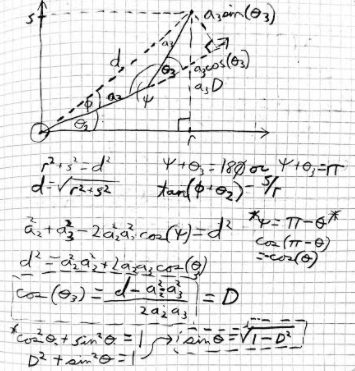 

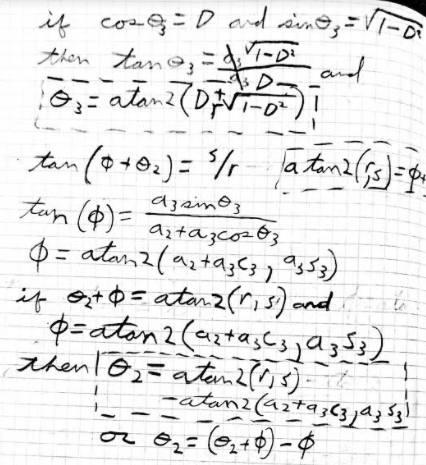

First, the links $a_2$ and $a_3$ are drawn as projected onto the plane formed by the 2 links. The end effector at the end of the 2 links is at position (*r,s*) in the plane.  A right triangle of base *r* and height *s* can be established and its hypotenuse *d *is labeled. Drawing this right triangle yields a triangle formed by links $a_2$, $a_3$ and d. There are 2 angles that may be identified: $\psi$, the angle between $a_2$ and $a_3$ and $\phi$, the angle between *d *and $a_2$. These additional angles are useful in that:


$$\psi +\theta_3 =\pi$$


and


$$\tan \left(\phi +\theta_2 \right)=\frac{s}{r}$$


We can use the Law of Cosines to obtain an equation that includes $\psi$:


$$a_2^2 +a_3^2 -2a_2 a_3 \cos \left(\psi \right)=d^2$$


Bearing in mind the identity $\cos \left(\pi -\theta \right)=-\cos \left(\theta \right)$ we can get an equation that directly relates $\theta_3$ to the geometric parameters of the manipulator:


$$\cos \left(\theta_3 \right)=\frac{d^2 -a_2^2 -a_3^2 }{2a_2 a_3 }:=D$$


as in Equation 5.24 in Spong et al. As $\cos \left(\theta_3 \right)=D$, a right triangle can be constructed with $a_3$ as a hypotenuse, $a_3 \cos \left(\theta_3 \right)$ or $a_3 D$ as the adjacent side and $a_3 \sin \left(\theta_3 \right)$ as the opposite side. The identity $\cos^2 \left(\theta \right)+\sin^2 \left(\theta \right)=1$ gives:


$$\sin \left(\theta \right)=\sqrt{1-D^2 }$$


as an alternative definition for the opposite side of said triangle. 

From this we can get $\theta_3$ in terms of an $\textrm{atan2}$ relationship as 


$$\theta_3 =\textrm{atan2}\left(D,\pm \sqrt{1-D^2 }\right)$$


as Spong et al. makes clear in Equation 5.25.

$\theta_2 \;$can be similarly described in terms of an arctangent relationship. As $\tan \left(\phi +\theta_2 \right)=\frac{s}{r}$, 

 
$$\phi +\theta_2 =\textrm{atan2}\left(r,s\right)$$


Similarly, $\phi$ can be described by a tangent relationship from a right triangle formed by an adjacent side consisting of $a_2 +a_3 \cos \left(\theta_3 \right)$ and an opposite side of $a_3 \sin \left(\theta_3 \right)$. Explicitly this is,


$$\phi =\textrm{atan2}\left(a_2 +a_3 \cos \left(\theta_3 \right),a_3 \sin \left(\theta_3 \right)\right)$$


Arctangent equations for $\phi +\theta_2$ and $\phi$ are known. It follows that we can subtract one from the other to yield,


$$\theta_2 =\left(\phi +\theta_2 \right)-\phi =\textrm{atan2}\left(r,s\right)-\textrm{atan2}\left(a_2 +a_3 \cos \left(\theta_3 \right),a_3 \sin \left(\theta_3 \right)\right)$$


### Problem Statement V-2:

With $\theta_1 ,\theta_2 \;,d_3 ,\textrm{and}\;\theta_4$ expressed in terms of physical manipulator attributes and/or and arctangents, it is possible to calculate these individual joint variables for a given end effector position. For the end effector positon we are given the following formulas for the X, Y and Z coordinates (in meters):

- 
$$x_c =0\ldotp 3+0\ldotp 1\sin \left(0\ldotp 5\pi t\right)$$


- 
$$y_c =0\ldotp 1+0\ldotp 1\cos \left(0\ldotp 5\pi t\right)$$


- 
$$z_c =0\ldotp 05+0\ldotp 01\sin \left(0\ldotp 1\pi t\right)$$


We first define the equations for the joint variables.

We will make the following initial assumptions regarding the link lengths of the SCARA manipulator. These dimensions are based on (but are not necessarily equivalent to) the Denso HSR series SCARA robot and are:


$$d_1 =252\textrm{mm}$$



$$d_4 =94\mathrm{mm}$$



$$a_1 =205\textrm{mm}$$



$$a_2 =275\mathrm{mm}$$


While we make these assumptions as a guide, these variables are implemented with slide controls to see how varying the individual parameters of the manipulator affects the individual joint angle when solving for the inverse kinematic equations. 

With this in mind, we can define the equations for each end effector coordinate within a loop and iterate over the variable *t* to get the x,y and z value for each coordinate in the end-effector path:

%initialize arrays to save on memory allocation
x_c = zeros(1,1001);
y_c = zeros(1,1001);
z_c = zeros(1,1001);
%get end effector coordinate arrays
count=1; %needed to increment array position
for t = 0:0.01:10
    x_c(1,count) = 0.3+0.1*sin(0.5*pi*t);
    y_c(1,count) = 0.1+0.1*cos(0.5*pi*t);
    z_c(1,count) = 0.05+0.01*sin(0.1*pi*t);
    count=count+1;
end

Plotting the end effector coordinates yields the path of the end effector

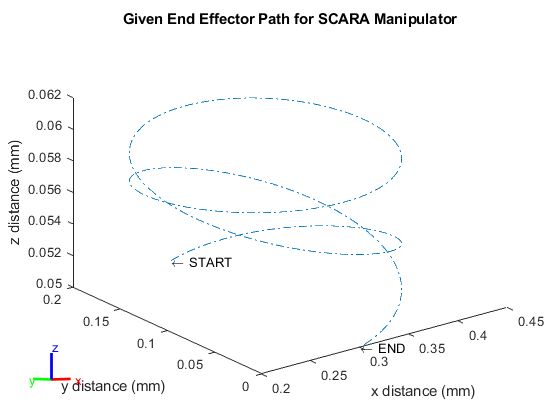

plot3(x_c,y_c,z_c,"-.");
title('Given End Effector Path for SCARA Manipulator')
text(x_c(1,1),y_c(1,1),z_c(1,1),"\leftarrow START");
text(x_c(1,1001),y_c(1,1001),z_c(1,1001),"\leftarrow END");
xlabel('x distance (mm)');
ylabel('y distance (mm)');
zlabel('z distance (mm)');

With the path coordinates defined, we can define each joint variable using the equations developed in the Materials and Methods section.

%link parameters - constants
d_1 = 0.252;
d_4 = 0.094 ;
a_1 = 0.205;
a_2 = 0.275;

%initialize arrays 
d_3 = zeros(1,1001);
s2 = zeros(1,1001);
c2 = zeros(1,1001);
theta1= zeros(1,1001);
theta2= zeros(1,1001);
theta4= zeros(1,1001);

for j = 1:1001
%define d_3
d_3(1,j) = d_1 - z_c(1,j) - d_4;

%define c2 aka cosine of theta2
c2(1,j) = (x_c(1,j)^2 + y_c(1,j)^2 - a_1^2 - a_2^2)/(2*a_1*a_2);

%define s2 aka sine of theta2
s2(1,j) = sqrt(1-c2(1,j)^2);

%define theta2 in terms of c2 and s2
theta2(1,j) = atan2(s2(1,j),c2(1,j));

%define theta1
theta1(1,j) = atan2(y_c(1,j),x_c(1,j))-atan2(a_2*s2(1,j),a_1+a_2*c2(1,j));

%define theta4
theta4(1,j) = theta1(1,j)+theta2(1,j);
end

The positions of $\theta_1 ,\theta_2 \;\textrm{and}\;d_3$ as the coordinates `x_c, y_c `and `z_c` are varied can now be graphed:

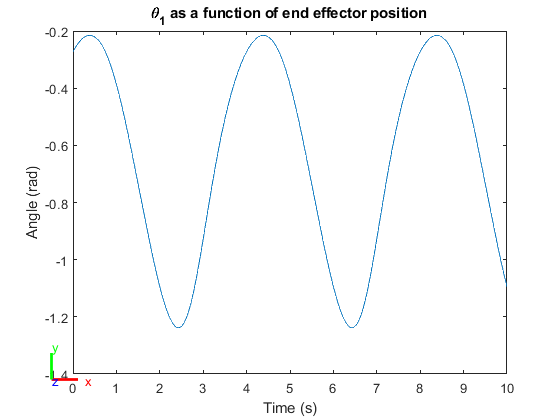

plot(0:.01:10,theta1)
title("\theta_1 as a function of end effector position")
xlabel('Time (s)')
ylabel('Angle (rad)')

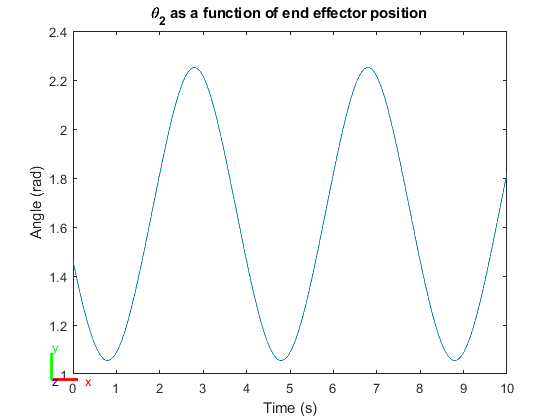

plot(0:.01:10,theta2)
title('\theta_2 as a function of end effector position')
xlabel('Time (s)')
ylabel('Angle (rad)')

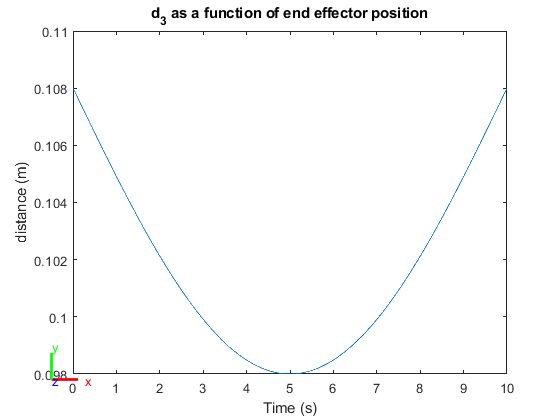

plot(0:.01:10,d_3)
title('d_3 as a function of end effector position')
xlabel('Time (s)')
ylabel('distance (m)')

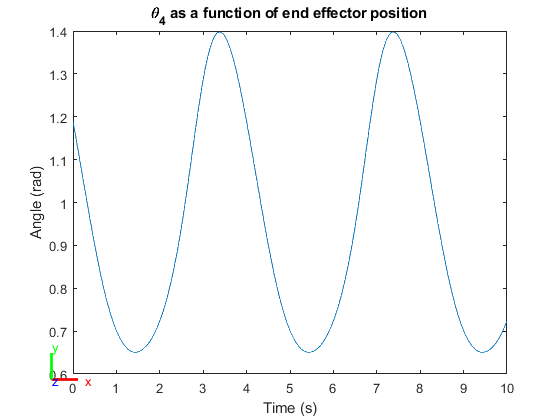

plot(0:.01:10,theta4)
title('\theta_4 as a function of end effector position')
xlabel('Time (s)')
ylabel('Angle (rad)')

### Problem Statement V-3:

Using the MATLAB Robotics Toolbox, it is relatively easy to construct a SCARA manipulator as a `RigidBodyTree` object. We do this with the `examplescara.m` file provided to us for the week 4 assignment.  

%Create a rigid body tree
robot = robotics.RigidBodyTree;

%Define the DH parameters. Note that the joint variables are zero
dhparams  = [.205 0 .252 0;
    .275 pi .062 0;
    0 0 .094 0;
    0 0 0 0]

dhparams =     0.2050         0    0.2520         0
    0.2750    3.1416    0.0620         0
         0         0    0.0940         0
         0         0         0         0


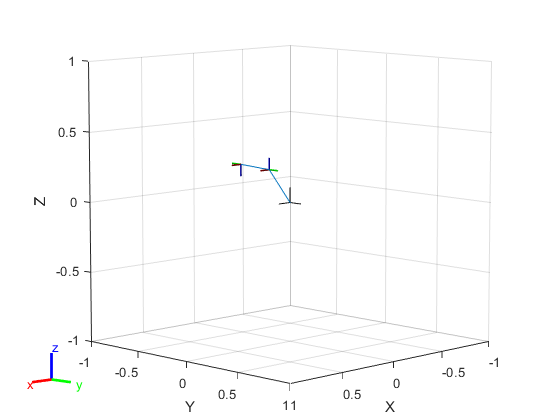


%Define the bodies and their joints
body1 = robotics.RigidBody('body1');
jnt1 = robotics.Joint('jnt1','revolute'); %Create a revolute joint.
body2 = robotics.RigidBody('body2');
jnt2 = robotics.Joint('jnt2','revolute'); %Create a revolute joint.
body3 = robotics.RigidBody('body3');
jnt3 = robotics.Joint('jnt3','prismatic'); %Create a prismatic joint.
body4 = robotics.RigidBody('body4');
jnt4 = robotics.Joint('jnt4','revolute'); %Create a revolute joint.

%Specify the body-to-body transformation using DH parameters
setFixedTransform(jnt1,dhparams(1,:),'dh');
setFixedTransform(jnt2,dhparams(2,:),'dh');
setFixedTransform(jnt3,dhparams(3,:),'dh');
setFixedTransform(jnt4,dhparams(4,:),'dh');

body1.Joint = jnt1;
body2.Joint = jnt2;
body3.Joint = jnt3;
body4.Joint = jnt4;

%attach the bodies
addBody(robot,body1,'base');
addBody(robot,body2,'body1');
addBody(robot,body3,'body2');
addBody(robot,body4,'body3');

%Robot configuration
config = homeConfiguration(robot);

show(robot,config);

With the SCARA manipulator modelled as the `robot` object, we can now use the inverseKinematics solver on the model to obtain the individual joint positions for a given end effector path. 

t = (0:.1:10);
count = length(t);
ik = inverseKinematics('RigidBodyTree',robot);
weights = [0 0 0 1 1 1];
endEffector = 'body4';
guess = homeConfiguration(robot);
ndof = length(guess);
qs = zeros(count,ndof);

for i = 1:count
    x=0.3+0.1*sin(0.5*pi*t(i));
    y=0.1+0.1*cos(0.5*pi*t(i));
    z=0.05+ 0.01*sin(0.1*pi*t(i));
    point= trvec2tform([x,y,z]);
    q_Sol = ik(endEffector,point,weights,guess);
    qs(i,:)=[q_Sol(1).JointPosition q_Sol(2).JointPosition q_Sol(3).JointPosition q_Sol(4).JointPosition];
    guess = q_Sol;
    
end

In the code above, which is largely taken from a MATLAB inverseKinematics tutorial, we first establish a time array `t` for the `t`-dependent end effector coordinate equations. We then instantiate an inverseKinematics object for our `robot` SCARA model. Weights are assigned to the x,y and z orientation solution and the x, y and z position solution. Above, as we only care about position for this particular exercise, we weight each orientation solution as 0 and each position solution as 1. `guess `is the initial solution guess for the inverse kinematics problem and is initialized to the home configuration of the SCARA `robot` object. `qs` is the solution matrix of the inverse kinematic problem that holds the solutions for each joint variable as individual columns, with a new row being the joint position need for each successive end effector position. 

A loop is set up to iterate the x,y, and z coordinate of the end effector. For each iteration, the inverseKinematics solver object `ik` computes a solution for the individual joint variables when passed the location, or the `"point"` of the end effector in 3D space, the defined weights for the position and orientation solutions and the solution guess. The output of `ik` given these inputs is a 4x1 struct that contains the individual joint positions in each of its rows. These positions are collected in the matrix `qs` and retained for plotting. Finally, the `guess` is update to the current solution and the loop repeats. 

The solutions that the inverse kinematics solver i`nverseKinematics` yield can be plotted for each joint variable $\theta_1 ,\theta_2 ,d_3 \;\textrm{and}\;\theta_4$:

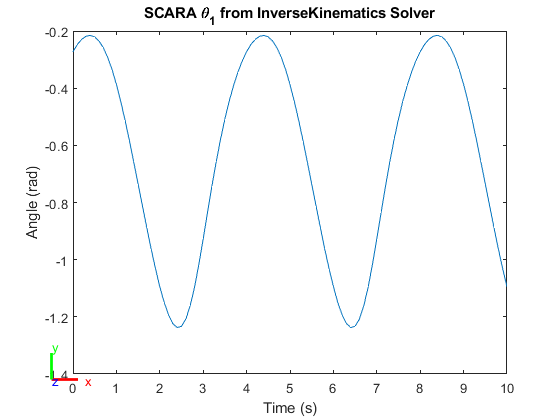

plot(t,qs(:,1));
title('SCARA \theta_1 from InverseKinematics Solver')
xlabel('Time (s)')
ylabel('Angle (rad)')

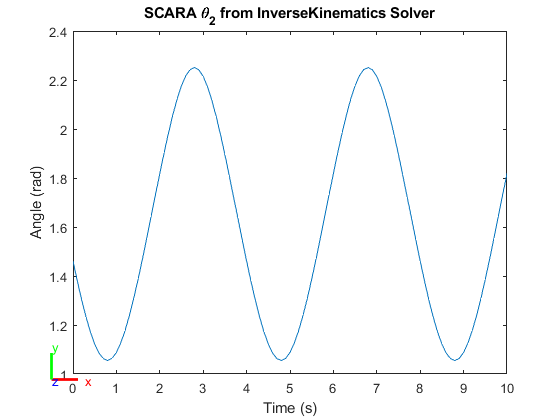

plot(t,qs(:,2));
title('SCARA \theta_2 from InverseKinematics Solver')
xlabel('Time (s)')
ylabel('Angle (rad)')

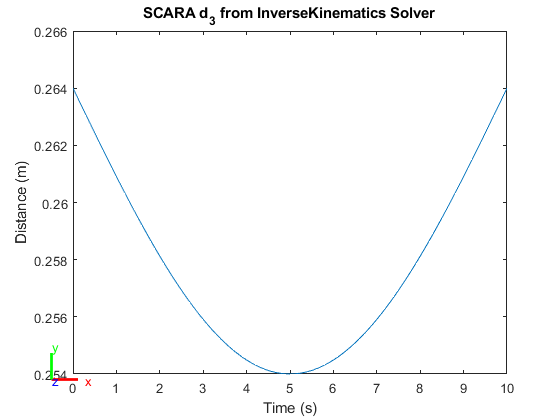

plot(t,qs(:,3));
title('SCARA d_3 from InverseKinematics Solver')
xlabel('Time (s)')
ylabel('Distance (m)')

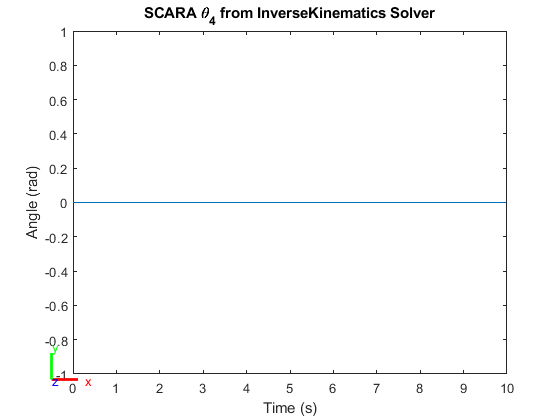

plot(t,qs(:,4));
title('SCARA \theta_4 from InverseKinematics Solver')
xlabel('Time (s)')
ylabel('Angle (rad)')

## Discussion:

### Problem Statement V-1:

Equations 5.25 and 5.26 were successfully derived for the elbow manipulator of Figure 5.8. The geometric method was used to derive expressions for $\theta_2$ and $\theta_3$ for the side projection of a 3-link elbow manipulator. The expressions are in terms of trigonometric relationships present on the manipulator. These relationships consist principally of the link lengths and their cosine and sine lengths.

Importantly, the expressions for $\theta_2 \;\mathrm{and}\;\theta_3$ were defined in terms of `atan2`, which allows for the retention of quadrant information. This is useful as the `tan` function otherwise has some ambiguity in terms of quadrant in accepting only one input. That is to say, the angle gotten from `tan` may be the angle it produces, or it may be that angle with an additive 180 degrees that lies in a quadrant directly opposite. Furthermore, `tan` is undefined if given a 0 for an x-value. Thus, `atan2` is clearly the preferred expression for joint angles.  

### **Problem Statement V-2:**

The inverse kinematic equations for the individual joint variables of a 4-axis SCARA manipulator were obtained. As in Problem Statement V-1, the geometric approach was taken to compute the expressions for the individual joint variables. All joint variables were expressed in terms of arctangent relationships with the function `atan2`. The solutions for the joint variables were then programmed into MATLAB and were graphed for a stepped end effector coordinate path with x, y, and z coordinates being defined by sinusoidal equations. Additionally, the SCARA link lengths were implemented using sliding controls to explore the effects of varying the link lengths on the joint variables. 

The results graphing the joint variables for an end-effector path are intuitively pleasing. All of the resultant graphs for the joint variables are also sinusoids, which one would expect if the end effector follows a sinusoidal path. Varying the link lengths $a_1 ,a_2 ,d_1 \;\mathrm{and}\;d_4$ seems to have the effect of altering the amplitude of the graphed joint variable position throughout the path. It does not seem to change the frequency nor the overall shapes of the graphs. This makes sense, in that the rate of change of the path is exclusively determined by the frequency of the sinusoidal equations that determine the end effector position. Furthermore, it makes sense that altering the link lengths would alter the joint angles and primatic joint stroke distance in that it directly affects the pose of the manipulator and also the rotations and distance travelled needed to position the links to achieve the end effector position. 

### Problem Statement V-3:

A 4-axis SCARA robot was successfully modelled using the MATLAB Robotics Toolbox and the InverseKinematics solver was successfully used to obtain the individual joint variable values for a given end effector path. This end effector path was identical to the one used in Problem Statement V-2 for a SCARA robot.

The results of the InverseKinematics solver are congruent with the joint positions graphed in Problem Statement V-2. The graphs of both, when compared, look the same, at least in shape. In amplitude, there is a difference between the $d_3$ graph from Problem Statement V-2 and the $d_3$ graph gotten from using InverseKinematics, but this is largely due to differences in how the link offset is defined for either implementation. 

There was a good deal of discussion among the class as to how to obtain a believable solution from the InverseKinematics solver. Varying the weighting of the orientation and position solutions greatly affects the output of the solver. For example, setting the `weight` array to [0.25 0.25 0.25 0.75 0.75 0.75] yielded the following graph for $\theta_1$:

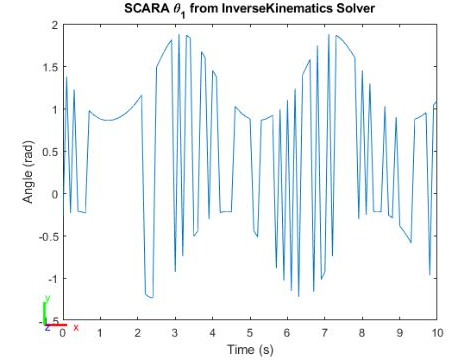

What appears to be happening is that the InverseKinematics solver "jumps" between possible solutions for $\theta_1$ with every few successive increments along the end effector path. The result is the envelope-like graph where the outside of the either side of the envelope cooresponds to a potential solution for the path. This is further thought to be the case because the offset of the upper envelope edge is positive while the offset of the lower envelope edge is negative, implying an opposing yet potentially equally correct solution for the position of $\theta_1$.

Also of note is the flat graph of $\theta_4$, the rotation of the end effector gotten from the InverseKinematics solver. This contradicts the graph of $\theta_4$ gotten in Problem Statement V-2. While it is unclear as to exactly why this is, the presence of all zeros in the DH table for link 4 of the `robot` object, the fact that the weighting of the orientation solutions is zero and the fact that the rotation of this particular end effector has no influence on the position of the end effector are all potential reasons. More work would need to be done to confirm if any of these are responsible for the output seen in the graph. 

## References:

-  Spong, M. W. (2006). *Robot Modelling and Control Mark W. Spong* (pp. 141-162) (926186803 726311037 M. W. Spong, Author). Hoboken, NJ: Wiley.

- [Comparison of InverseKinematics solver algorithms](https://www.mathworks.com/help/robotics/ug/inverse-kinematics-algorithms.html)

- [InverseKinematics solver tutorial](https://www.mathworks.com/help/robotics/ug/2d-inverse-kinematics-example.html)

- [Denso Robot Catalog (For HSR Specs)](https://dc-docs.dcatalog.com/Densocompany/Robotics/72c75621-8544-41b4-9afa-a7f60153efbd/DENSO_Robotics_Catalog_D2277470.pdf?v=16000223827980.19439691676377646)